**fplot (구 ezplot)**

하나의 변수로 표현된 심볼릭 수식의 그래프를 그림

title, xlabel 명령어를 사용하지 않아도 자동으로 제목과 *x*축의 이름이 표시 

**형식: fplot(E,[xmin.xmax])**

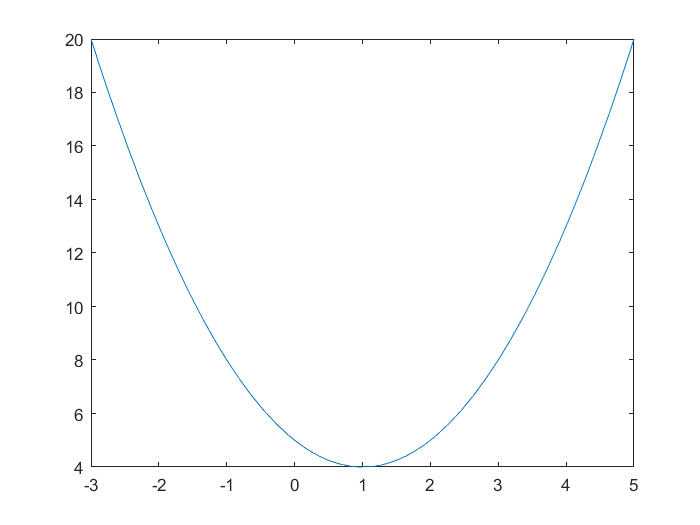

syms x
e1=x^2-2*x+5;
fplot(e1,[-3,5])

만약 y축 제목 추가하고 싶으면, 아래를 수행한다.

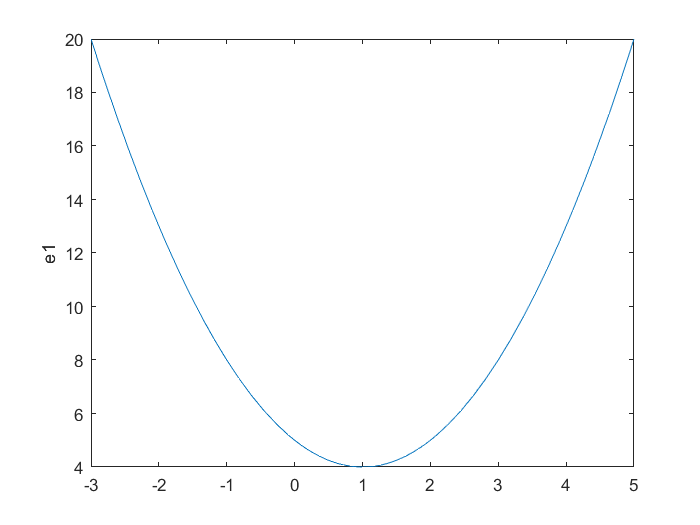

ylabel('e1');

**solve**

심볼릭 방정식의 해를 구함.

예 방정식 *x *+ 5 = 0을 풀기 

syms x
solve(x+5==0)

$$ans = -5$$

syms x
f1 = x+5==0;
solve(f1)

$$ans = -5$$

syms x
x = solve(x+5)

$$x = -5$$

exp(2*x)+3*exp(x)==54, 풀려면 (혹시 live editor로 않되면 work window에서 한다.)

syms x
solve(exp(2*x)+3*exp(x)==54)

$$ans = \left(\begin{array}{c} \log\left(6\right)\\ \log\left(9\right)+\pi \,\mathrm{i} \end{array}\right)$$

eq3 = x^2+9*y^4==0에서 아무말 없으면 x가 변수라고 생각하고 방정식 푼다. 

syms x y
eq3 = x^2+9*y^4==0;
solve(eq3)

$$ans = \left(\begin{array}{c} -3\,y^{2}\,\mathrm{i}\\ 3\,y^{2}\,\mathrm{i} \end{array}\right)$$

그래서 다변수 방정식에서는 변수를 미리 지정할 필요가 있다.

다음은 위 방정식을 y를 변수로 지정하고 푼다.

syms x y
eq3 = x^2+9*y^4==0;
solve(eq3,y)

$$ans = \left(\begin{array}{c} -\frac{{\left(-1\right)}^{1/4}\,9^{3/4}\,\sqrt{x}}{9}\\ \frac{{\left(-1\right)}^{1/4}\,9^{3/4}\,\sqrt{x}}{9}\\ -\frac{{\left(-1\right)}^{1/4}\,9^{3/4}\,\sqrt{x}\,\mathrm{i}}{9}\\ \frac{{\left(-1\right)}^{1/4}\,9^{3/4}\,\sqrt{x}\,\mathrm{i}}{9} \end{array}\right)$$

연립 방정식 풀기

6x+2y=14

3x+7y=31

syms x y
f1=6*x+2*y==14

$$f1 = 6\,x+2\,y=14$$

f2=3*x+7*y==31

$$f2 = 3\,x+7\,y=31$$

solve(f1,f2)

ans = 다음 필드를 포함한 struct :
    x: [1×1 sym]
    y: [1×1 sym]


위 답은 변수가 특별히 지정되지 않아서 무조건 ans변수에 자동 저장된다.

x와 y를 각각 보려면,

x=ans.x

$$x = 1$$

y=ans.y

$$y = 4$$

위 연립 방정식을 풀면서 바로 x,y애 집어 넣으려면,

syms x y
f1=6*x+2*y==14

$$f1 = 6\,x+2\,y=14$$

f2=3*x+7*y==31

$$f2 = 3\,x+7\,y=31$$

[x,y]=solve(f1,f2);
x

$$x = 1$$

y

$$y = 4$$